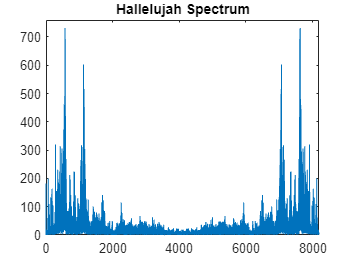

% 
load handel.mat  
x = y'; 
x = x(1:65536);

% Calculate FFT and freq axis 
Y = fft(y); 
freqInc = Fs / length(Y); 
freqAxis = 0:freqInc:(Fs - freqInc); 

% Plot spectrum
plot(freqAxis, abs(Y)) 
title("Hallelujah Spectrum")
axis([0 8191 0 760])

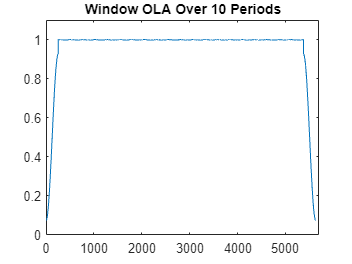


% Attempt deconstruction and reconstruction
% by windowed FFT 

% Process variables
winSize = 512; 
ovrlapSF = 2; 
outp = zeros(1, length(x));

% Plot window with chosen overlap to check COLA 
w = hamming(winSize)'; 
checkCOLA(w, length(w))

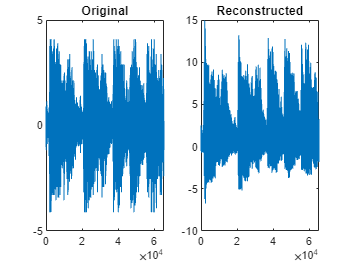


% Loop over samples and update window, 
% apply STFT to window, apply IFFT to window, 
% overlap add to output array 
for i = 0 : (length(x) / winSize) * 2 - 2
    % Calculate boundaries of current window
    St = i * winSize/2 + 1;                 % Current window start pos
    Mid = (i + 1) * winSize/2;        % Current window mid pos 
    End = Mid + winSize/2;            % Curr window end pos
    % Update current window from samples
    samples = x(St : End);
    samples = samples .* w; 
    % Compute spectrum 
    S = fft(samples); 
    % ** Spectral Analysis **  
    R = abs(S); 
    I = angle(S); 
    I = zeros(1, length(I)); 
    S = R + I;
    % Return to time domain
    samples = ifft(S);
    % Overlap add reconstruct
    outp(1, St : Mid) = outp(1, St : Mid) + samples(1 : winSize/2); % Overlap add
    outp(1, (Mid+1) : End) = samples(winSize/2+1:end);            % Append
end 

% Compare input sample with output sample reconstruction
subplot(1, 2, 1)
plot(normalize(x)) 
title('Original')
subplot(1, 2, 2)
plot(normalize(outp)) 
title('Reconstructed')


figure;
t = 0:.1:10; 
x = sin(t) 

x =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


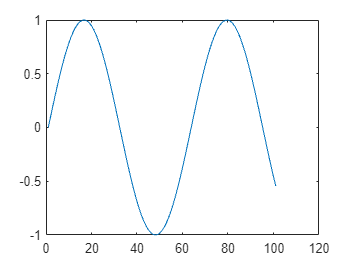

plot(x) 

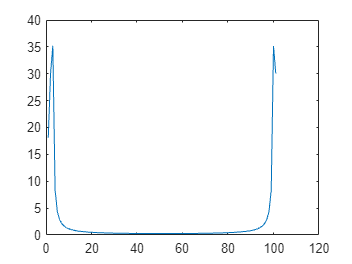

X = fft(x); 
plot(abs(X))

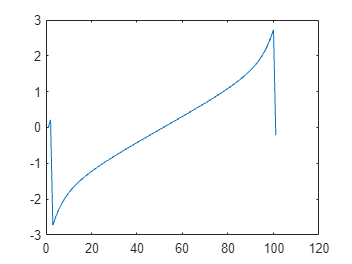

plot(angle(X))